## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
%file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
 file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/realistic_params.json";
simulator.load_params_from_JSON(file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 18.44 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.20 MSps
	 Ramp End Time: 		 26.56 us
	 Chirp Tx Bandwidth: 		 26.56 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 20.00 us
	 Chirp Cycle Time: 		 45.00 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 11.52 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.67 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 1110.34 m/s
	 Velocity Resolution 		 8.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 28.80 MHz
	 Downsampling factor 		 9
	 Sweep time 			 26.56 us
	 Samples per chirp 		 1296.00 


## Configure the Tx Data File

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/chirp_full.bin";
fileID = fopen(path,'w');
data = 0.3 *double(simulator.Victim.chirp);
fwrite(fileID,reshape([real(data),imag(data)].',[],1), 'float32');
fclose(fileID);

## Plot Tx Chirp to confirm correctness

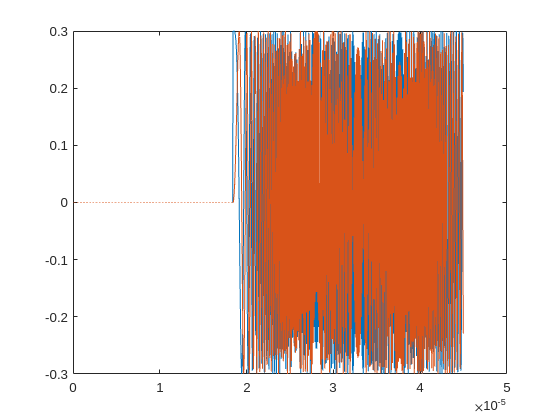

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
plot(t,real(data),t,imag(data))

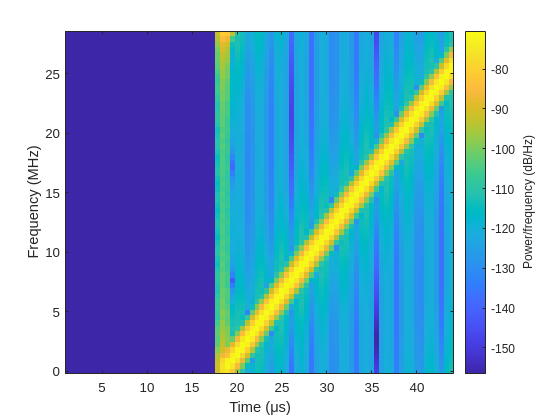

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Read the Rx Data File

%to open a file from the GNU radio saved to a binary file
num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
path = "/home/david/Documents/MATLAB_generated/rx_data.bin";
fileID = fopen(path,'r');
read_data = fread(fileID,'float');
read_data = reshape(read_data,2,[]).';
read_data = read_data(:,1) + 1j * read_data(:,2);

%reshape the data into the correct format
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);
%disp(read_data);
fclose(fileID);

## Plot Rx Chirp to confirm correctness

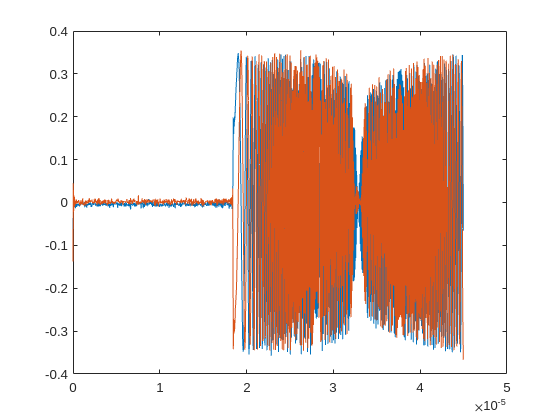

%plot the chirp signal
chirp = 251;
frame = 20;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))

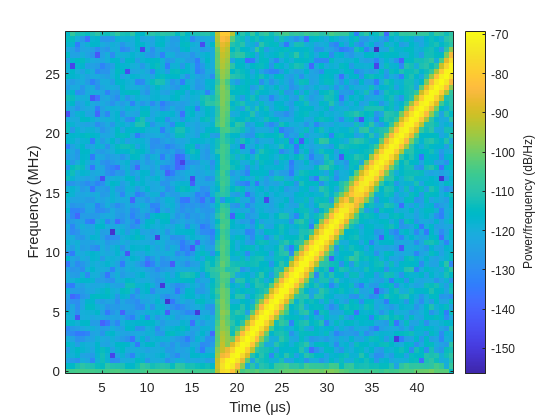

%plot(t,real(read_data(:,2,5)))
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

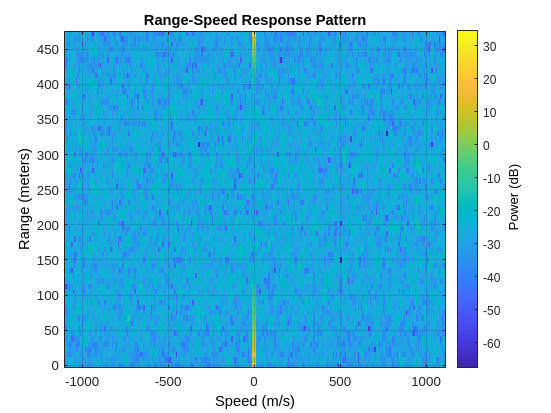

%specify the number of frames and chirps to compute
frames_to_compute = size(read_data,3);
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
simulator.Victim.precompute_radar_chirps();


%configure things to be able to generate a movie
F_output(frames_to_compute) = struct('cdata',[],'colormap',[]);

for frame = int32(1:frames_to_compute)
    
    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = read_data(:,chirp,frame);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %plot the doppler response and save it for a movie
%     subplot(1,2,1);
    plotResponse(simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse,radar_cube);

%NOTE: CFAR DISABLED FOR NOW BECAUSE IT NEEDS TO BE TUNED
%     %CA CFAR 2-D
%     detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
%     detected_velocities = dopgrid(detections(2,:));
%     detected_ranges = rnggrid(detections(1,:));
%     
%     %DBSCAN Clustering
%     if (~isempty(detections))
%         idx = dbscan(detections.',simulator.Victim.Radar_Signal_Processor.Epsilon,simulator.Victim.Radar_Signal_Processor.minpts);
%         
%         %plot the clusters
%         subplot(1,2,2);
%         gscatter(detected_velocities,detected_ranges,idx);
%         axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
%     
%         %estimate the range and the velocities
%         rngest = simulator.Victim.Radar_Signal_Processor.RangeEstimator(resp,rnggrid,detections,idx.');
%         dopest = simulator.Victim.Radar_Signal_Processor.DopplerEstimator(resp,dopgrid,detections,idx.');
%     end
    drawnow
    F_output(frame) = getframe(gcf);
end

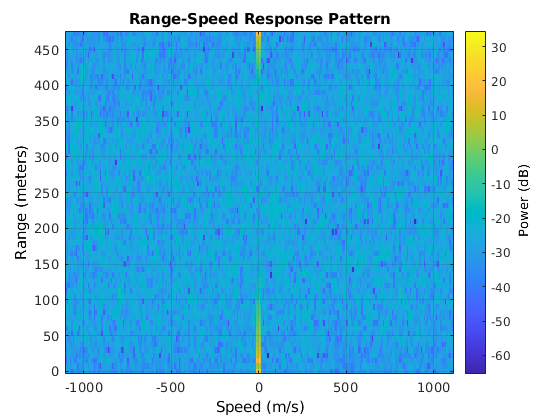

%play the movie for the output
clf;
fig = figure;
movie(fig,F_output,1,10);

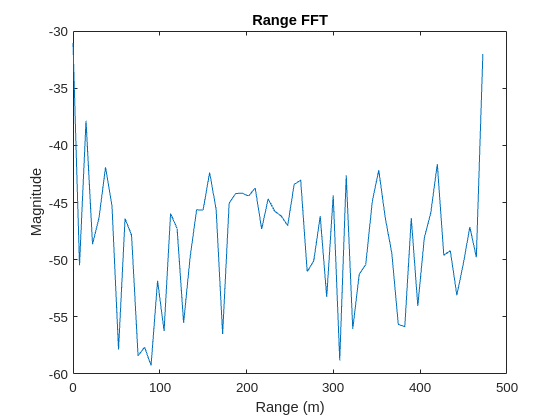

window = hann(simulator.Victim.ADC_Samples);
windowed_sig = window .* radar_cube(:,1);
range_fft = 20 * log10(abs(fft(windowed_sig)));
clf;
plot(simulator.Victim.Ranges,range_fft)
xlabel("Range (m)");
ylabel("Magnitude");
title("Range FFT")

## Code to align the rx and the tx signal using cross correlation

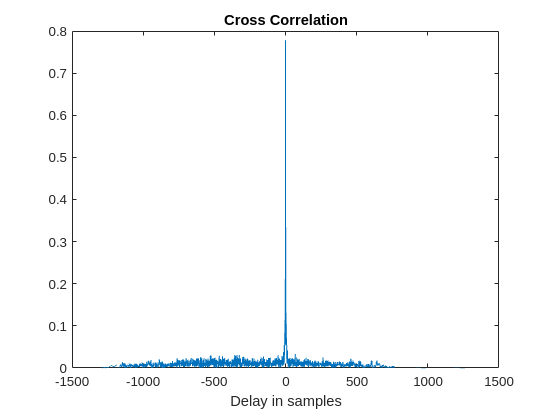

[C,lag] = xcorr(Rx_sig,Tx_sig,"normalized");
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")

[M,I] = max(abs(C));
delay_samps = lag(I)

delay_samps = 0

delay_us = delay_samps * simulator.Victim.FMCW_sampling_period_s * 1e6

delay_us = 0

% plot(lag,C,[t21 t21],[-0.5 1],'r:')
% text(t21+100,0.5,['Lag: ' int2str(t21)])
% ylabel('C_{21}')